# Matlab scripts

%
clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');                 % Complex Variable

numG = 0.7;                             % numerator
denG = 0.0196*s^3+0.1876*s^2+1.168*s+1; % denominator

% Overførings Funktion 
G = numG/denG;
    bode(G)              % bodeplot
[mag,phase] = bode(G,w); % Magnitude og Phase til Func
mag = squeeze(mag);
phase = squeeze(phase);

% vairabler
ym=60;    % Phase margin
Ni=2;     % Ni
a=1;      % Alpha til Lead   

%Ni = wc*tau_i  % anden måde at regne tau i ud på. 

% Phase bidrag
phCi = atand(-1/Ni);  % I-leads phase contribution
phCm = asind((1-a)/(1+a));  % D leds phase cont  
    Gphas=-180+ym-phCi-phCm % Total phase contribution + wanted phase margin. 

% Finding the wanted phase margin
% NB NB !!! remember to look at bodeplot to see where we wont to find it 
% 
p_c =find(phase > Gphas,1,'last');
wc=w(p_c);  % calculated 
% wc = 1;    % Defined 

% Tids konstanter til Tau_D og I
tau_i = Ni*(1/wc)
tau_d = 1/(sqrt(a)*wc);
% I / D TF.
Ci = ((tau_i*s+1)/(tau_i*s));
Cd = (tau_d*s+1)/(tau_D*a*s+1);

% Lead Magnitude og Gain
M_d=1/(sqrt(a));
Kplead = 1/(abs(freqresp(G,wc)*M_d);




Kpi = 1/(abs(freqresp(Ci*G,wc)));
% Kpd = 1/(abs(freqresp(Cd*G,wc))); % Tror ikke denne er relevant. 


## Bode plot ana


%
clf;
clear all;
clc;

% Rising the KP so that we get a proper wc 
% Read bodeplot and get db at wanted freq se sæt 23/3

Kp = db2mag(15.33); % - omvendt fortegn da vi hæver den.

Kp = 5.8412

## Forsøgs


%
clf;
clear all;
clc;
b=db2mag(2.5)

b = 1.3335

syms a 

eqn = b == 1/(sqrt(a))

$$eqn = \frac{1501411656245329}{1125899906842624}=\frac{1}{\sqrt{a}}$$

sol1 = solve(eqn,a)

$$sol1 = \frac{1267650600228229401496703205376}{2254236961509341976369834318241}$$

var1 = double(sol1)

var1 = 0.5623

## KP brute force

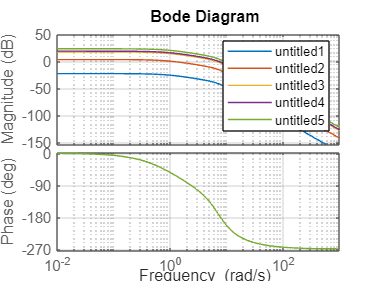

%
clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');                 % Complex Variable

% Definer fun
numG = 0.7;                             % numerator
denG = 0.0196*s^3+0.1876*s^2+1.168*s+1; % denominator

Kp1 = 0.1;
Kp2 = 2;
Kp3 = 10;
Kp4 = 12;
Kp5 = 20;


G = numG/denG;
 
hold on;
legend;
bode(G*Kp1)
bode(G*Kp2)
bode(G*Kp3)
bode(G*Kp4)
bode(G*Kp5)
grid on;
hold off;

## Closed Loop y(0)/y(uendelig)

% y(0) fjern s og udregn 

step(Gcl) % Closed loop G/1+G 
step(Gfb) % G*Kp osv. 



## Løs linærer systemer

clf;
clear all;
clc;
%      Første model brugt

s = tf('s');
syms x1 x2 u s y

eqn1 = s*x1 == -2*x1 + x2 + u

$$eqn1 = s\,x_{1}=u-2\,x_{1}+x_{2}$$

eqn2 = s*x2 == -3*x2 + 3*u

$$eqn2 = s\,x_{2}=3\,u-3\,x_{2}$$

eqn3 = y == x2

$$eqn3 = y=x_{2}$$


solx1= solve(eqn1, u,x1)

solx1 = struct with fields:
     u: -x2
    x1: 0


solx2 = solve(eqn2,x2)

$$solx2 = \frac{3\,u}{s+3}$$

solve1 = solve(eqn3,x2)

$$solve1 = y$$

 
ysolve =
 
Empty sym: 0-by-1
 


## Zeta og andet

clf;
clear all;
clc;

syms G(s) zeta w_n s Mp pi e w_c gamma_m atan
 G(s) == w_n^2/(s^2+2*zeta*w_n^2+w_n^2)

$$ans = G\left(s\right)=\frac{{w_{n}}^{2}}{2\,{w_{n}}^{2}\,\zeta +s^{2}+{w_{n}}^{2}}$$

piz=pi*zeta;
sq2=sqrt(1-(zeta^2)) % der mangler et minus foran pi. 

$$sq2 = \sqrt{1-\zeta^{2}}$$


 Mp == e^((piz)/sq2)

$$ans = \mathrm{Mp}=e^{\frac{\pi \,\zeta }{\sqrt{1-\zeta^{2}}}}$$


 w_c==w_n*(sqrt(sqrt(1+4*zeta^4)-2*zeta^2))

$$ans = w_{c}=w_{n}\,\sqrt{\sqrt{4\,\zeta^{4}+1}-2\,\zeta^{2}}$$


%  gamma_m == atan*(((2*zeta)/(sqrt(sqrt(1+4*zeta^4)-2*zeta^2))))

$$ans = \gamma_{m}=\frac{2\,\text{atan}\,\zeta }{\sqrt{\sqrt{4\,\zeta^{4}+1}-2\,\zeta^{2}}}$$